% AAE 532 HW 6 Problem 2
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps6';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortG;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
mars = planet_consts.mars;  % structure of mars
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
Re         = earth.mer;  % Earth radius
mu         = earth.gp;  % gravitational parameter
a          = 3*Re;  % semi major axis
e          = 0.6;  % eccentricity 
p          = a * (1 - e^2);  % semi latus rectum
E          = -90;  % true anomaly at maneuver point
M          = rad2deg(deg2rad(E) - sind(E))

M =       -32.704


TA         = E2T_anomaly(e, E, "deg")

TA =        233.13


r1         = p / (1 + e * cosd(TA));          
v1         = vis_viva(r1, a, mu);         
h          = sqrt(mu * p);  % specific angular momentum
FPA1       = -acosd(h / r1 / v1)  % flight path angle

FPA1 =        -36.87


dt_1p      = deg2rad(360+M)*sqrt(a^3 / mu)

dt_1p =         23948


dt_1p_day  = dt_1p / 60 / 60 / 24

dt_1p_day =       0.27718


ra         = a*(1+e); rp = a*(1-e); b = a*sqrt(1-e^2);

r1vec_o    = r1 * [1, 0];

r1vec_o =         19134            0


r1vec_i    = r1 * [cosd(TA), sind(TA)];

r1vec_i =        -11481       -15308


v1vec_o    = v1 * [sind(FPA1), cosd(FPA1)];

v1vec_o =       -2.7385       3.6513


v1vec_i    = v1vec_o * [cosd(TA), sind(TA); -sind(TA), cosd(TA)];

v1vec_i =        4.5642   3.5527e-15


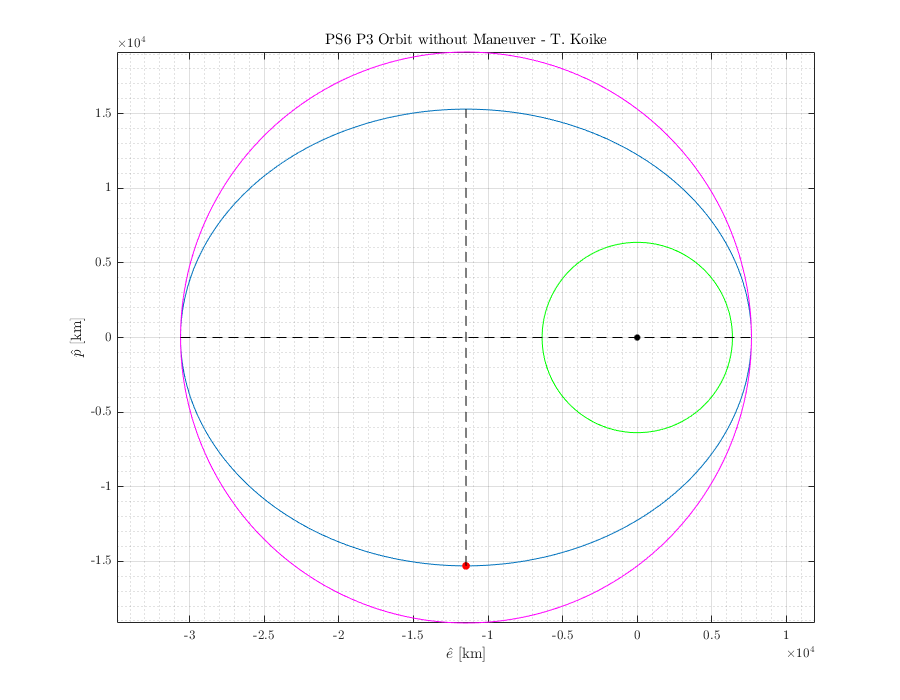

% Plotting for visualization 
% old orbit
angles = 0:0.01:2*pi;
RR = p ./ (1 + e*cos(angles)); XX = RR.*cos(angles); YY = RR.*sin(angles);

% Reference circle
Xref = a*cos(angles)-a*e; Yref = a*sin(angles);

% new orbit
% RR_new = p_new ./ (1 + e_new*cos(angles - deg2rad(Domega)));
% XX_new = RR_new.*cos(angles);
% YY_new = RR_new.*sin(angles);
% rp_vec = rp_new*[cosd(Domega), sind(Domega)];
% ra_vec = ra_new*[cosd(Domega+180), sind(Domega+180)];

% Earth
Xearth = Re*cos(angles); Yearth = Re*sin(angles);

fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
plot(XX,YY)
hold on; grid on; grid minor; box on; axis equal; 
% Maneuver point
plot(r1vec_i(1), r1vec_i(2), '.r', 'MarkerSize', 20)
% Center of orbit
plot(0,0,'.k', 'MarkerSize', 15)
% Reference circle
plot(Xref, Yref, '-m')
% Semi minor axis
plot([-a*e, -a*e], [-b, b], '--k')
% Earth
plot(Xearth, Yearth, '-g')
% plot(XX_new, YY_new, '-m')
plot([-ra, rp], [0, 0], '--k')
% plot([ra_vec(1), rp_vec(1)],[ra_vec(2), rp_vec(2)], '--r')
hold off
title('PS6 P3 Orbit without Maneuver - T. Koike')
xlabel('$\hat{e}$ [km]')
ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, "p3-orbit-noManeuver.png"))

% New orbit after maneuver 
rp2 = 2*Re

rp2 =         12756


e2 = 0.4

e2 =           0.4


a2 = rp2 / (1 - e2)

a2 =         21260


p2 = a2 * (1 - e2^2)

p2 =         17859


r2 = r1

r2 =         19134


TA2 = acos_dbval(1/e2 * (p2/r2 - 1), "deg")

TA2 =        99.594      -99.594


v2 = vis_viva(r2, a2, mu)

v2 =        4.7869


FPA2 = acos_dbval(sqrt(mu*p2)/r2/v2, "deg")

FPA2 =        22.908      -22.908


TA2_eval1 = TAfromRVGamma(r2, v2, FPA2(1), mu, "deg") 

TA2_eval1 =       -80.406       99.594


TA2_eval2 = TAfromRVGamma(r2, v2, FPA2(2), mu, "deg")

TA2_eval2 =        80.406      -99.594


FPA2 = FPA2(FPA2 < 0)

FPA2 =       -22.908


TA2 = TA2(TA2 < 0)

TA2 =       -99.594


r2vec_o = r2 * [1, 0];
v2vec_o = v2 * [sind(FPA2), cosd(FPA2)]

v2vec_o =       -1.8633       4.4094


dvvec_o = v2vec_o - v1vec_o

dvvec_o =       0.87519      0.75807


dv = norm(dvvec_o)

dv =        1.1579


alpha = acos_dbval(dot(v1vec_o, dvvec_o)/v1/norm(dvvec_o), "deg")

alpha =        85.971      -85.971


alpha = alpha(alpha > 0)

alpha =        85.971


dvvec_VBN = dv * [cosd(alpha), sind(alpha)]

dvvec_VBN =      0.081344        1.155


rp2 = a2*(1-e2)

rp2 =         12756


ra2 = a2*(1+e2)

ra2 =         29765


IP = 2*pi*sqrt(a2^3/mu)

IP =         30851


IP_day = IP / 60 / 60 / 24

IP_day =       0.35707


En = -mu/2/a2

En =       -9.3742


E2 = T2E_anomaly(e2, TA2, "deg")

E2 =       -75.522


dt_2p = (deg2rad(360 + E2) - sind(360 + E2))*sqrt(a2^3/mu)

dt_2p =         29133


dt_2p_day = dt_2p / 60/60/24

dt_2p_day =       0.33719


Domega = (TA-360) - TA2  

Domega =       -27.276


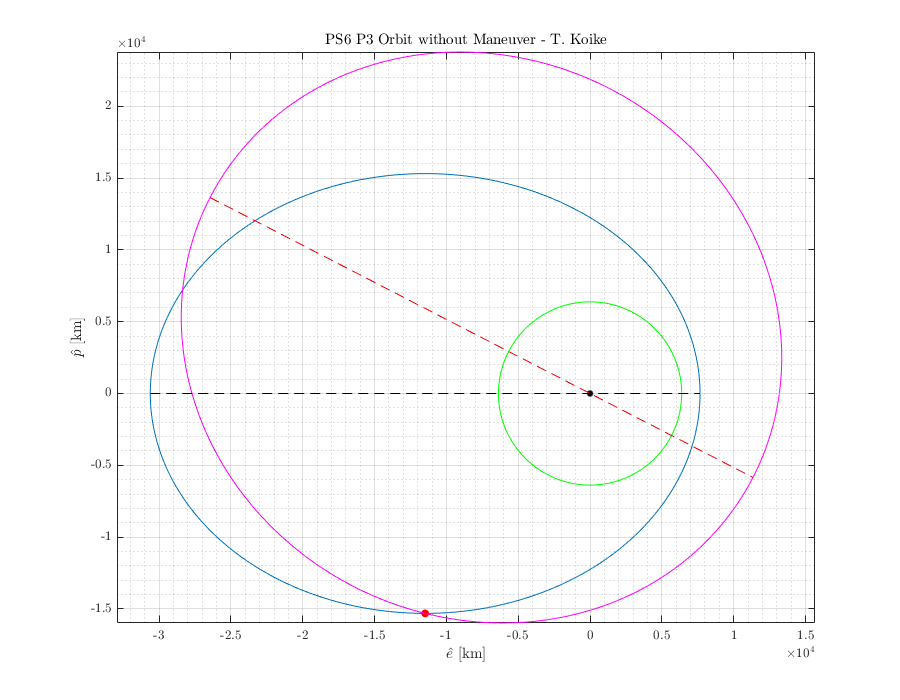

% Plotting for visualization 
% old orbit
angles = 0:0.01:2*pi;
RR = p ./ (1 + e*cos(angles)); XX = RR.*cos(angles); YY = RR.*sin(angles);

% Reference circle
% Xref = a*cos(angles)-a*e; Yref = a*sin(angles);

% new orbit
RR_new = p2 ./ (1 + e2*cos(angles - deg2rad(Domega)));
XX_new = RR_new.*cos(angles);
YY_new = RR_new.*sin(angles);
rp_vec = rp2*[cosd(Domega), sind(Domega)];
ra_vec = ra2*[cosd(Domega+180), sind(Domega+180)];

% Earth
Xearth = Re*cos(angles); Yearth = Re*sin(angles);

fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
plot(XX,YY)
hold on; grid on; grid minor; box on; axis equal; 
% Maneuver point
plot(r1vec_i(1), r1vec_i(2), '.r', 'MarkerSize', 20)
% Center of orbit
plot(0,0,'.k', 'MarkerSize', 15)

% Reference circle
% plot(Xref, Yref, '-m')

% Semi minor axis
% plot([-a*e, -a*e], [-b, b], '--k')

% Earth
plot(Xearth, Yearth, '-g')
plot(XX_new, YY_new, '-m')
plot([-ra, rp], [0, 0], '--k')
plot([ra_vec(1), rp_vec(1)],[ra_vec(2), rp_vec(2)], '--r')
hold off
title('PS6 P3 Orbit without Maneuver - T. Koike')
xlabel('$\hat{e}$ [km]')
ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, "p3-orbit-withManeuver.png"))

function TA = TAfromRVGamma(r, v, gamma, mu, unit)
    A = r*v^2/mu;
    if unit == "rad"
        gamma = rad2deg(gamma);
    end
    num = A*cosd(gamma)*sind(gamma);
    den = A*cosd(gamma)^2 - 1;
    TA = atan_dbval(num/ den, unit);
end